数据录入

clear

DP = zeros(1,108);
for i = 1:108
    DP(i) = nan;
end
DP(3:4) = 71.359;
DP(7:8) = 64*60+34.016;
DP(21:22) = 64*60+49.531;
DP(51) = 1 *60+47.328;
DP(52) = 1 *60+43.844;
DP(53) = 0 *60+34.125;
DP(54) = 0 *60+23.500;
DP(55) = 64 *60+31.516;
DP(56) = 64 *60+35.734;
DP(57) = 64 *60+23.672;
DP(58) = 68 *60+6.359;
DP(63:66) = 0 *60+0.094;
DP(67:68) = 0 *60+0.109;
DP(69:76) = 0 *60+0.109;
DP(77:108) = 0 *60+0.109;

TTD1_org = load('计时Cp.txt');
TTD1_org = TTD1_org';
TTD1 = zeros(1,108);
for i = 1:108
    TTD1(i) = NaN;
end
j = 1;
for i = [1:58 63:108]
    TTD1(i) = TTD1_org(j);
    j = j + 1;
end

TTD2 = load('计时.txt');
TTD2 = TTD2';

SABTD_org = load('计时0.txt');
SABTD_org = SABTD_org';
SABTD = zeros(1,108);
for i = 1:108
    SABTD(i) = NaN;
end
j = 1;
for i = [1:4 7:10 17:34 39 40 45:58 63:108]
    SABTD(i) = SABTD_org(j);
    j = j + 1;
end

load messages.mat
n = zeros(1,108);
for i = 1:108
    n(i) = length(messages(i).period);
end

按照消息数量排序

[n,idx] = sort(n);
DP = DP(idx);
SABTD = SABTD(idx);
TTD1 = TTD1(idx);
TTD2 = TTD2(idx);

整合消息数量相同的port

newn = [];
newDP = [];
newSABTD = [];
newTTD1 = [];
newTTD2 = [];

count = 0;
countSABTD = 0;
lastn = [];
tmpDP = [];
tmpSABTD = [];
tmpTTD1 = [];
tmpTTD2 = [];

for i = 1:108
    tmpn = n(i);
    if tmpn == lastn
        tmpDP = tmpDP + DP(i);
        tmpTTD1 = tmpTTD1 + TTD1(i);
        tmpTTD2 = tmpTTD2 + TTD2(i);  
        count = count + 1;
        
        if ~isnan(SABTD(i))
            tmpSABTD = tmpSABTD + SABTD(i);
            countSABTD = countSABTD + 1;
        end
    else
        newn = [newn lastn];
        newDP = [newDP tmpDP/count];
        newSABTD = [newSABTD tmpSABTD/countSABTD];
        newTTD1 = [newTTD1 tmpTTD1/count];
        newTTD2 = [newTTD2 tmpTTD2/count];
        
        count = 0;
        countSABTD = 0;
        lastn = tmpn;
        tmpDP = 0;
        tmpSABTD = 0;
        tmpTTD1 = 0;
        tmpTTD2 = 0;
    end
end
newn = [newn lastn];
newDP = [newDP tmpDP/count];
newSABTD = [newSABTD tmpSABTD/countSABTD];
newTTD1 = [newTTD1 tmpTTD1/count];
newTTD2 = [newTTD2 tmpTTD2/count];

画图

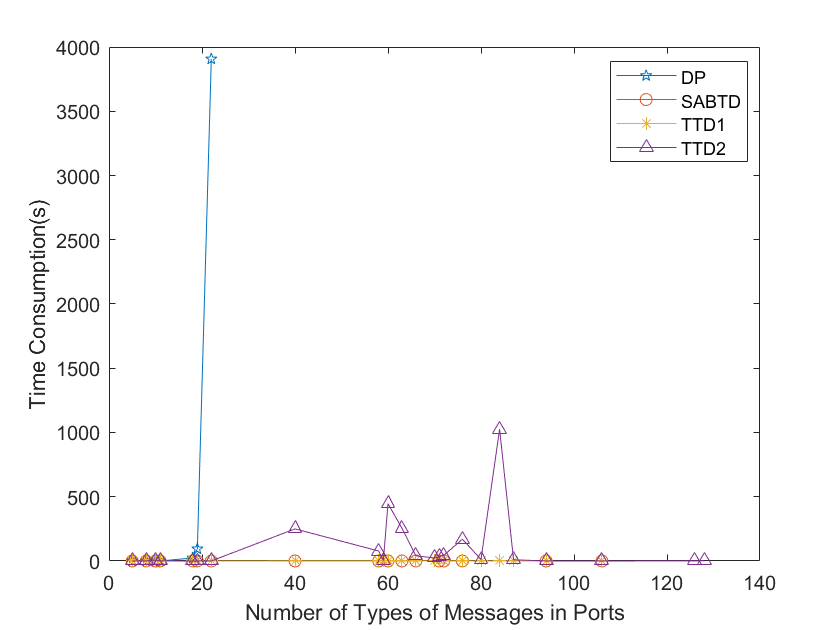

figure
plot(newn,newDP,'pentagram-')
hold on
plot(newn,newSABTD,'o-')
plot(newn,newTTD1,'*-')
plot(newn,newTTD2,'^-')
hold off
legend(["DP","SABTD","TTD1","TTD2"],'Location','best');
xlabel("Number of Types of Messages in Ports");
ylabel("Time Consumption(s)");

画图，inside的图

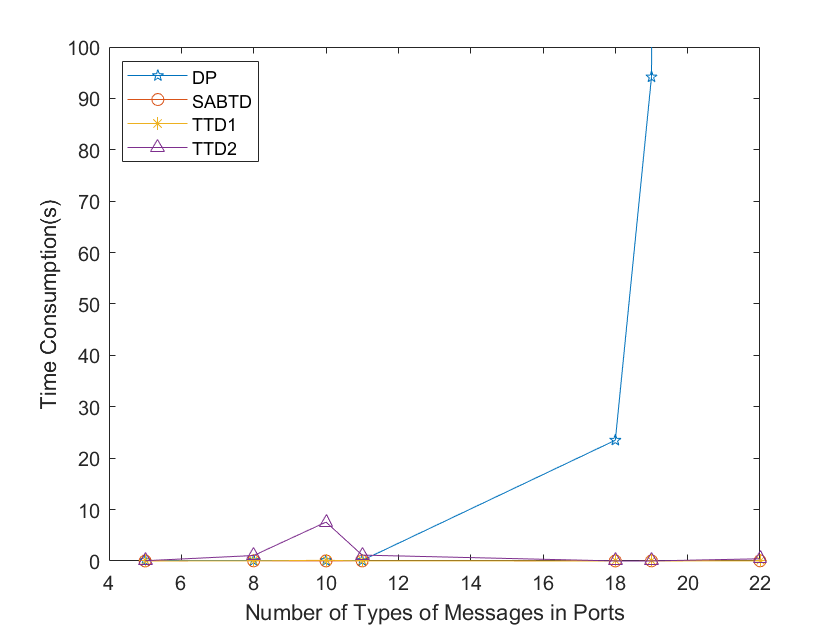

figure
plot(newn(1:7),newDP(1:7),'pentagram-')
hold on
plot(newn(1:7),newSABTD(1:7),'o-')
plot(newn(1:7),newTTD1(1:7),'*-')
plot(newn(1:7),newTTD2(1:7),'^-')
hold off
legend(["DP","SABTD","TTD1","TTD2"],'Location','best');
xlabel("Number of Types of Messages in Ports");
ylabel("Time Consumption(s)");
xlim([4 22]);
ylim([0 100]);

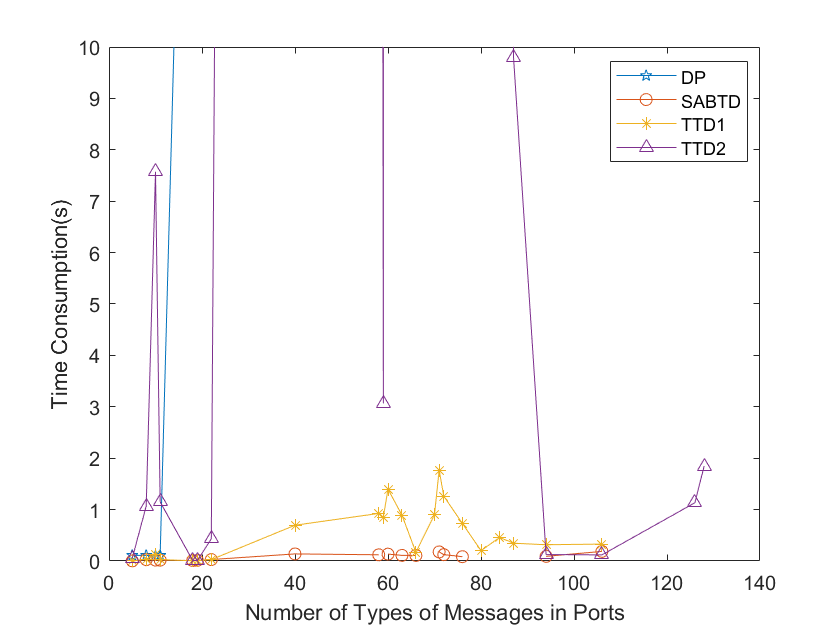

figure
plot(newn,newDP,'pentagram-')
hold on
plot(newn,newSABTD,'o-')
plot(newn,newTTD1,'*-')
plot(newn,newTTD2,'^-')
hold off
legend(["DP","SABTD","TTD1","TTD2"],'Location','best');
xlabel("Number of Types of Messages in Ports");
ylabel("Time Consumption(s)");
ylim([0 10]);

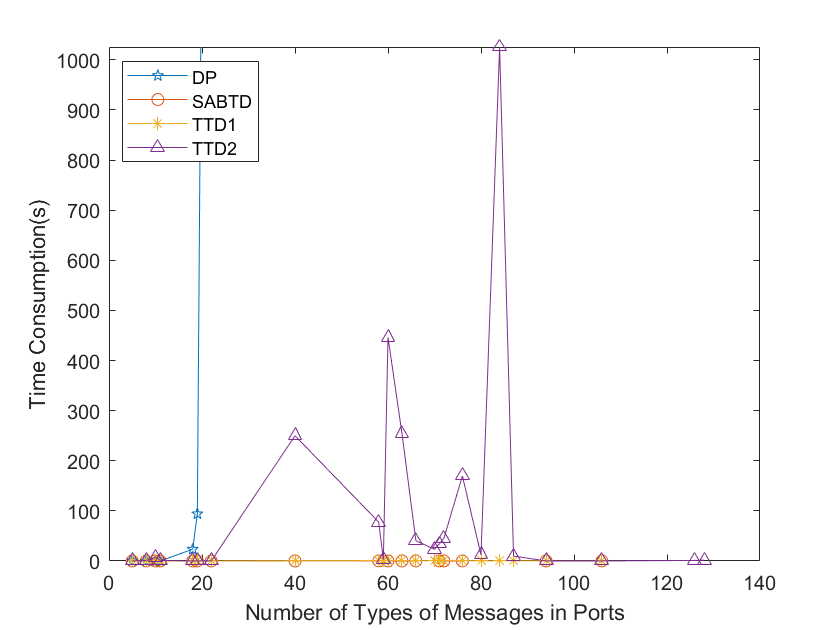

figure
plot(newn,newDP,'pentagram-')
hold on
plot(newn,newSABTD,'o-')
plot(newn,newTTD1,'*-')
plot(newn,newTTD2,'^-')
hold off
legend(["DP","SABTD","TTD1","TTD2"],'Location','best');
xlabel("Number of Types of Messages in Ports");
ylabel("Time Consumption(s)");
ylim([0 max(newTTD2)]);

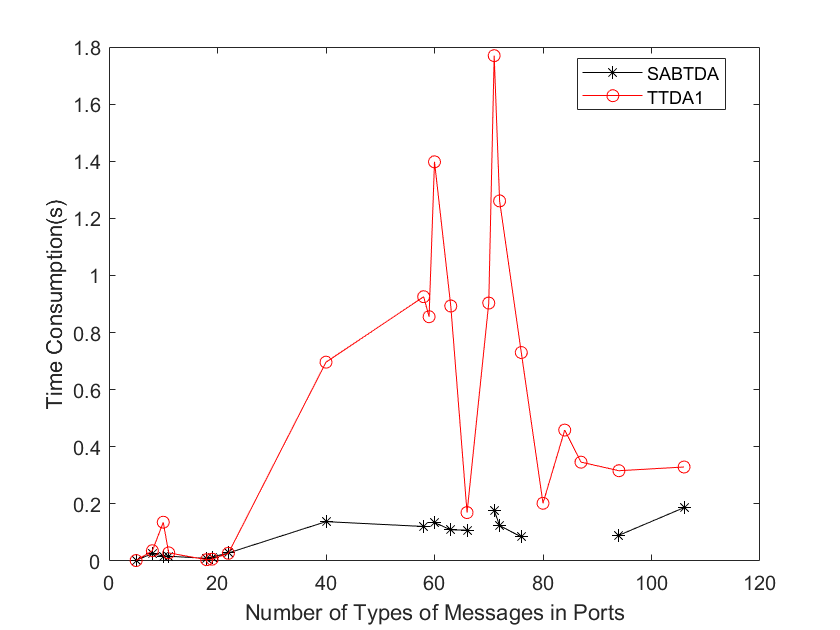

figure
plot(newn,newSABTD,'*-k')
hold on
plot(newn,newTTD1,'o-r')
hold off
legend(["SABTDA","TTDA1"],'Location','best');
xlabel("Number of Types of Messages in Ports");
ylabel("Time Consumption(s)");

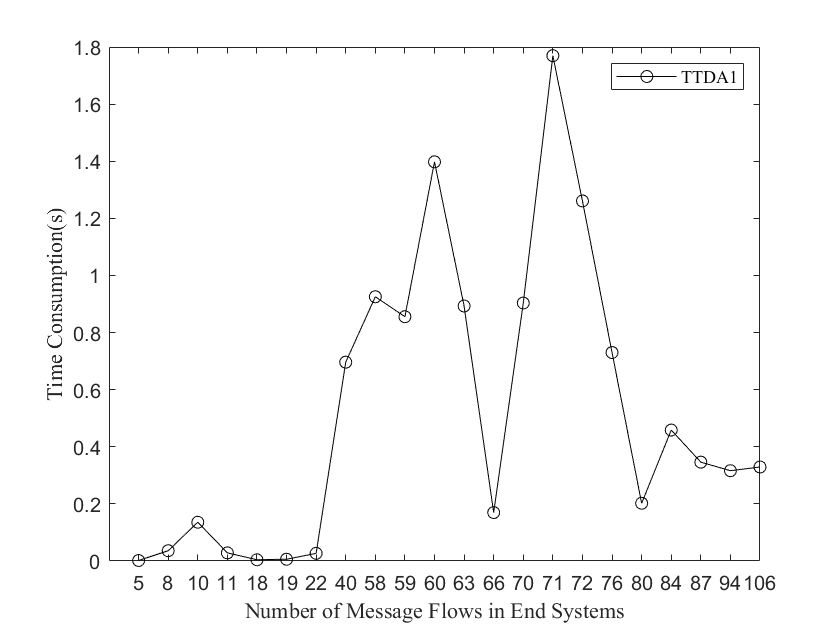

figure
uniformPort = 1:24;
idx1 = ~isnan(newSABTD);
idx2 = ~isnan(newTTD1);
uniformPort1 = uniformPort(idx1);
uniformPort2 = uniformPort(idx2);
%plot(uniformPort1,newSABTD(idx1),'*-r')
%hold on
plot(uniformPort2,newTTD1(idx2),'o-k')
%hold off
%legend(["SABTDA","TTDA1"],'Location','northeast','FontName','Times New Roman');
legend(["TTDA1"],'Location','northeast','FontName','Times New Roman');
xlabel("Number of Message Flows in End Systems",'FontName','Times New Roman');
ylabel("Time Consumption(s)",'FontName','Times New Roman');
xlim([0 22]);
xticks(uniformPort(idx2))
xticklabels(newn(idx2))

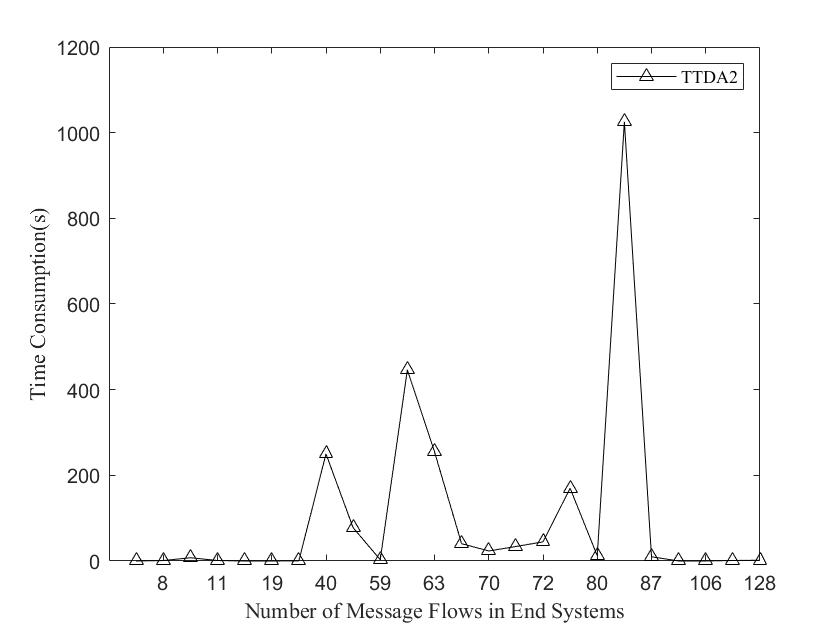

figure
uniformPort = 1:24;
plot(uniformPort,newTTD2,'^-k')
legend(["TTDA2"],'Location','northeast','FontName','Times New Roman');
xlabel("Number of Message Flows in End Systems",'FontName','Times New Roman');
ylabel("Time Consumption(s)",'FontName','Times New Roman');
xlim([0 24]);
labelPort = [2:2:24];
xticks(labelPort)
xticklabels(newn(labelPort))

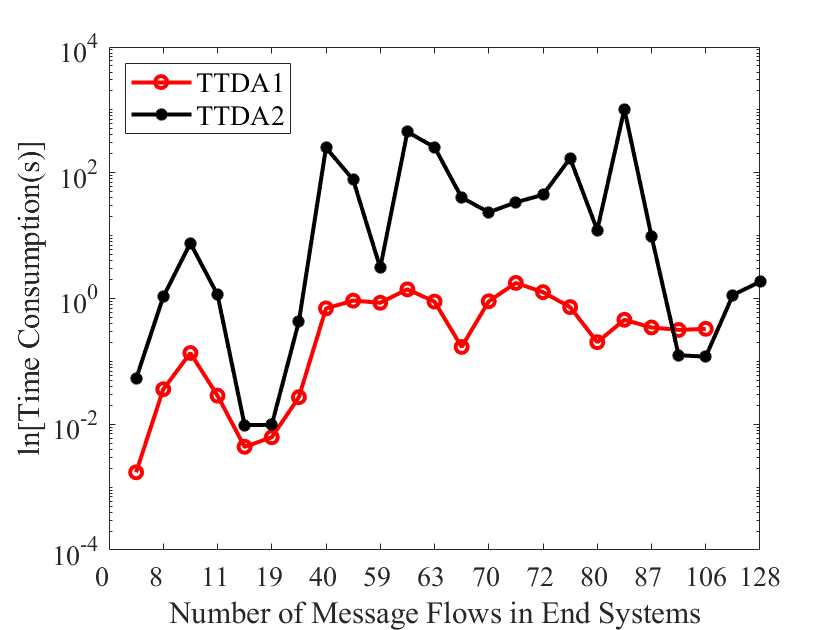

figure
uniformPort = 1:24;
idx2 = ~isnan(newTTD1);
uniformPort2 = uniformPort(idx2);
semilogy(uniformPort2,newTTD1(idx2),'o-r','LineWidth',2)
hold on
semilogy(uniformPort,newTTD2,'*-k','LineWidth',2)
hold off
legend(["TTDA1","TTDA2"],'Location','northwest','FontName','Times New Roman',"FontSize",14);
xlabel("Number of Message Flows in End Systems",'FontName','Times New Roman',"FontSize",14);
ylabel("ln[Time Consumption(s)]",'FontName','Times New Roman',"FontSize",14);
xlim([0 24]);
labelPort = [0:2:24];
%labelPort(1) = labelPort(1) + 0.3;
%labelPort(4:14) = labelPort(3:13);
%labelPort(3) = labelPort(2) + 0.3;
xticks(labelPort)
%labelPort = [0:2:24];
h = [0 newn(labelPort(2:13))];
set(gca,'XTickLabel',h,'fontsize',14, 'fontname','Times New Roman');

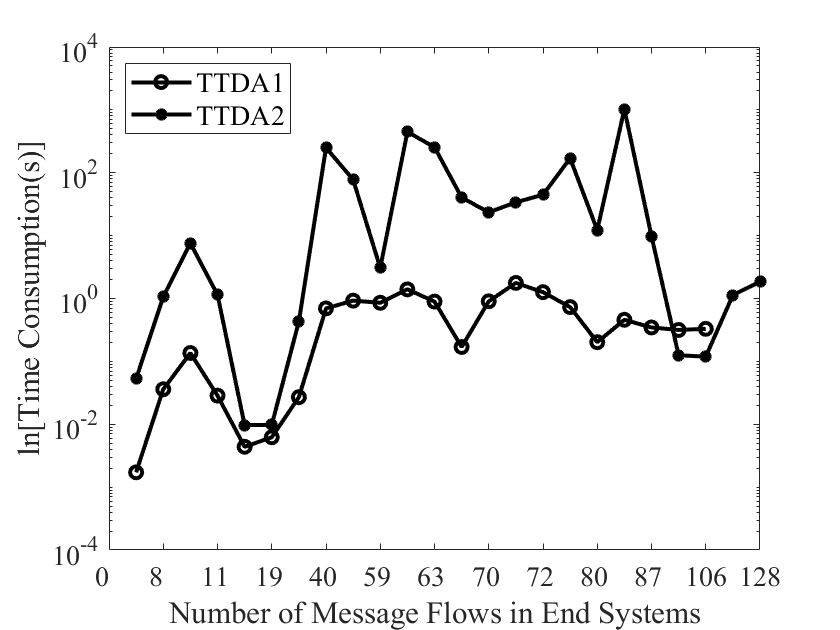

figure
uniformPort = 1:24;
idx2 = ~isnan(newTTD1);
uniformPort2 = uniformPort(idx2);
semilogy(uniformPort2,newTTD1(idx2),'o-k','LineWidth',2)
hold on
semilogy(uniformPort,newTTD2,'*-k','LineWidth',2)
hold off
legend(["TTDA1","TTDA2"],'Location','northwest','FontName','Times New Roman',"FontSize",14);
xlabel("Number of Message Flows in End Systems",'FontName','Times New Roman',"FontSize",14);
ylabel("ln[Time Consumption(s)]",'FontName','Times New Roman',"FontSize",14);
xlim([0 24]);
labelPort = [0:2:24];
xticks(labelPort)
h = [0 newn(labelPort(2:13))];
set(gca,'XTickLabel',h,'fontsize',14, 'fontname','Times New Roman');